Load the data and initialise training / testing split

trainLen = 2000;
testLen = 2000;
data = load('MackeyGlass_t17.txt');

Initialise leaky and sparsity hyperparameter and set seed for randomness

a = 0.8;
s = 0.01;
rand( 'seed', 1 );

## Main Reservoirs

The main reservoirs are stacked in a layer on top of one another and are each fed the current input concurrently. In the current build, the total number of nodes in this main reservoir layer is limited to 100 but can be altered if needed. The number of these reservoirs can also be redefined easily.

**NOTE: the number of reservoirs has to be a factor 100 in this build, *****fix()***** can be used to round if needed**

numberOfReservoirs = 2;
resSize = 100 / numberOfReservoirs;
inSize = 1;

Win and W are cell arrays that store the corresponding input and reservoir weights for each main reservoir.

[Win, W] = deal(cell(1,numberOfReservoirs));
for i = 1:numberOfReservoirs
    Win{i} = (rand(resSize,1+inSize)-0.5) .* 1;
    W{i} = rand(resSize,resSize)-0.5;

Spectral radius calculation.

    rhoW = abs(eigs(W{i},1,'LM'));
    W{i} = W{i} .* ( 1.25 /rhoW);

Set 1% (when s = 0.01) of connections in the reservoirs to 0 to induce connection sparstiy.

    for j = 1:numel(W{i})
        if rand > s
            W{i}(j) = 0;
        end
    end
    for j = 1:numel(Win{i})
        if rand > s
            Win{i}(j) = 0;
        end
    end
end

## Mini Reservoir

The mini reservoir collects main reservoir states at once in an attempt to collate the processing for a single usable output. In this build, the mini reservoir contains 20 nodes.

resSizeMini = 20;

The inputs for this reservoir are the nodes from every main reservoir so the input size is adjusted accordingly.

inSizeMini = resSize*numberOfReservoirs; outSizeMini = 1;

WinMini = (rand(resSizeMini,1+inSizeMini)-0.5) .* 1;
WMini = rand(resSizeMini,resSizeMini)-0.5;
rhoW = abs(eigs(WMini,1,'LM'));
WMini = WMini .* ( 1.25 /rhoW);

for j = 1:numel(WMini)
    if rand > s
        WMini(j) = 0;
    end
end
for j = 1:numel(WinMini)
    if rand > s
        WinMini(j) = 0;
    end
end

## Training

Initialise the reservoir state matrix containing every node state (input nodes, main reservoir nodes, mini reservoir nodes, and bias) as 0s for training. Also initialise the target data matrix using the imported datase.

X = zeros(1+numberOfReservoirs*(inSize+resSize)+resSizeMini);
Yt = data(2:trainLen+1)';

Initialise an array that will contain a list of all current main reservoir node states, organised by reservoir. Initialise xMini to perform a similar purpose for the mini reservoir.

x = cell(1,numberOfReservoirs);
for i = 1:numberOfReservoirs
    x{i} = zeros(resSize,1);
end

xMini = zeros(resSizeMini,1);

Run the reservoirs with the data and collect the final node states.

for t = 1:trainLen    
	u = data(t);   

By finding the remainder of the reservoir index with the current step, we can determine whether that specific reservoir updates, which is done using the typical update equation.

    for i = 1:numberOfReservoirs
        if ~rem(t,i)
            x{i} = (1-a)*x{i} + a*tanh( Win{i}*[1;u] + W{i}*x{i} );
        end
    end

Similarly, update the mini reservoir state using an adapted state update equation that uses the entire main reservoir node array *x*

   	xMini = (1-a)*xMini + a*tanh( WinMini*[1;cell2mat(x')] + WMini*xMini ); 

Add all node values to the initialised state matrix for training

    X(:,t) = [1;repmat(u,1,numberOfReservoirs)';cell2mat(x');xMini];
end


Train the readout weights using 1e-8 as the training coefficient and the calculated X and Yt matrices.

reg = 1e-8;
Wout = Yt*X' * inv(X*X' + reg*eye(1+numberOfReservoirs*(inSize+resSize)+resSizeMini));

## Testing

Initialise the Y matrix that willl contain the predicted values using our model (and update reinitialise training step).

Y = zeros(outSizeMini,testLen);
u = data(trainLen+1);

Same code as the training loop with the addition of the *y* calculation as the output layer state (i.e. the predicted value). This is then added to the preinitialised Y matrix.

for t = 1:testLen 
    
    for i = 1:numberOfReservoirs
        if ~rem(t,i)
            x{i} = (1-a)*x{i} + a*tanh( Win{i}*[1;u] + W{i}*x{i} );
        end
    end
    
   	xMini = (1-a)*xMini + a*tanh( WinMini*[1;cell2mat(x')] + WMini*xMini );
    
	y = Wout*[1;repmat(u,1,numberOfReservoirs)';cell2mat(x');xMini];
	Y(:,t) = y;

	u = data(trainLen+t+1);
end

## Analysis

Calculate MSE and NMSE scores appropriately

errorLen = 500;
desired_output = data(trainLen+2:trainLen+errorLen+1)';
system_output = Y(1,1:errorLen);
mse = sum((desired_output-system_output).^2)./errorLen;
nmse = mean((desired_output - system_output).^2)/var(desired_output);
disp( ['MSE = ', num2str( mse ),' NMSE = ', num2str( nmse )] );

MSE = 2.3723e-05 NMSE = 0.00050296


Plot the target signal with the predicted signal overlayed on top

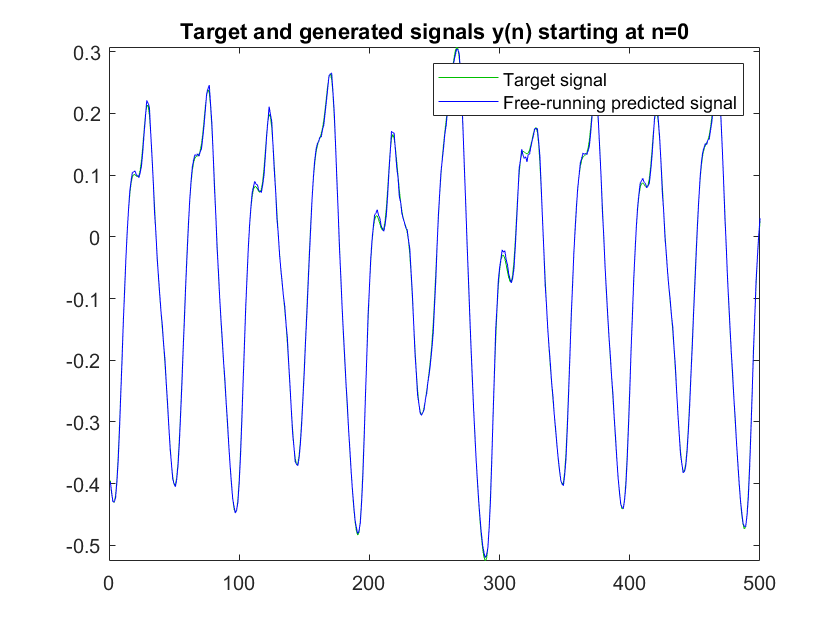

figure;
plot( data(trainLen+2:trainLen+testLen+1), 'color', [0,0.75,0] );
hold on;
plot( Y', 'b' );
hold off;
axis tight;
xlim([0 500]);
title('Target and generated signals y(n) starting at n=0');
legend('Target signal', 'Free-running predicted signal');